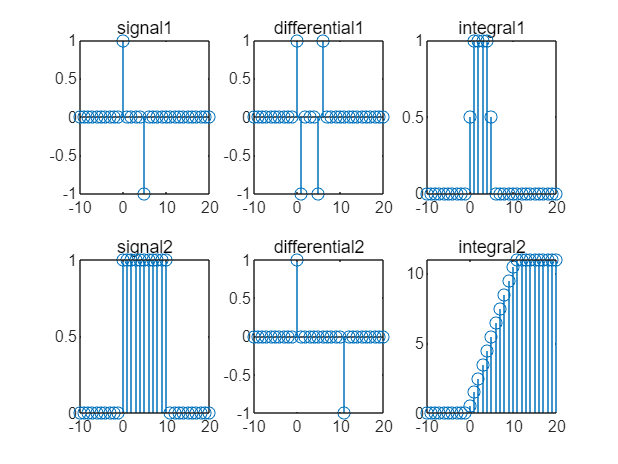

%2.3
n=-10:20;
x1=(n==0)-(n==5);
x2=(n>=0)-(n>=11);
yd1=differentiator(x1);
yd2=differentiator(x2);
yi1=integral(x1);
yi2=integral(x2);
figure
subplot(2,3,1)
stem(n,x1);
title('signal1')
subplot(2,3,2)
stem(n,yd1);
title('differential1')
subplot(2,3,3)
stem(n,yi1);
title('integral1')
subplot(2,3,4)
stem(n,x2);
title('signal2')
subplot(2,3,5)
stem(n,yd2);
title('differential2')
subplot(2,3,6)
stem(n,yi2);
title('integral2')

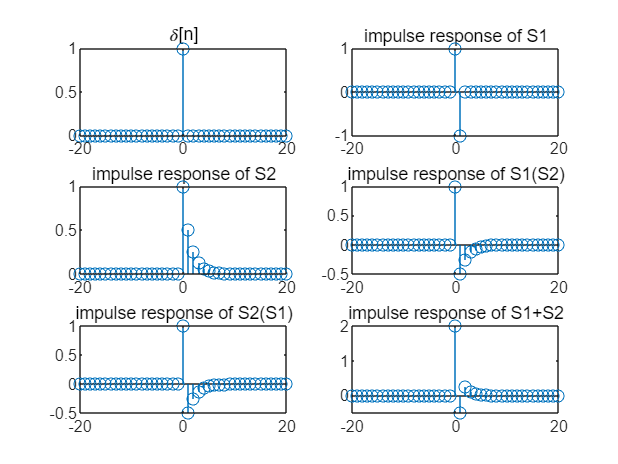

%2.4
n=-20:20;
x=(n==0);
y1=S1(x);
y2=S2(x);
y3=S2(S1(x));
y4=S1(S2(x));
y5=y1+y2;
figure
subplot(3,2,1)
stem(n,x);
title('\delta[n]');
subplot(3,2,2)
stem(n,y1);
title('impulse response of S1');
subplot(3,2,3)
stem(n,y2);
title('impulse response of S2');
subplot(3,2,4)
stem(n,y3);
title('impulse response of S1(S2)');
subplot(3,2,5)
stem(n,y4);
title('impulse response of S2(S1)');
subplot(3,2,6)
stem(n,y5);
title('impulse response of S1+S2');

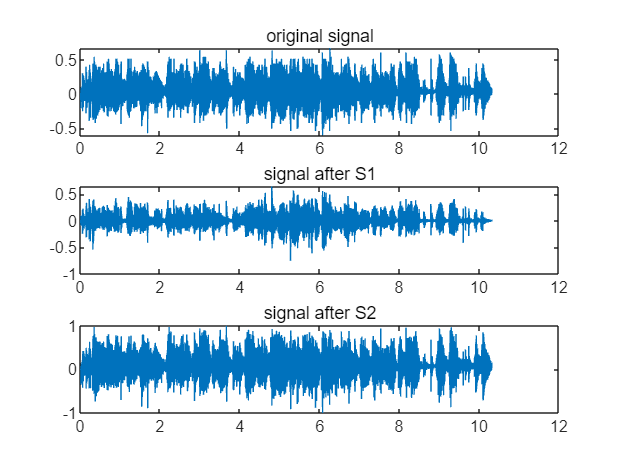

%2.5
figure
[x,fs]=audioread('music.au');
t=0:1/fs:(length(x)-1)/fs;
subplot(3,1,1)
plot(t,x);
title('original signal')
sound(x);
y1=S1(x);
y2=S2(x);
subplot(3,1,2)
plot(t,y1);
title('signal after S1')
subplot(3,1,3)
plot(t,y2);
title('signal after S2')

sound(y1);
sound(y2);

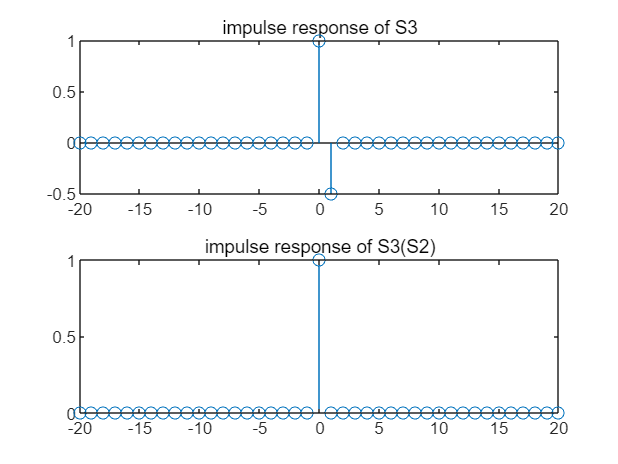

%2.6
n=-20:20;
x=(n==0);
y1=S3(x);
y2=S3(S2(x));
figure
subplot(2,1,1)
stem(n,y1);
title('impulse response of S3');
subplot(2,1,2)
stem(n,y2);
title('impulse response of S3(S2)');

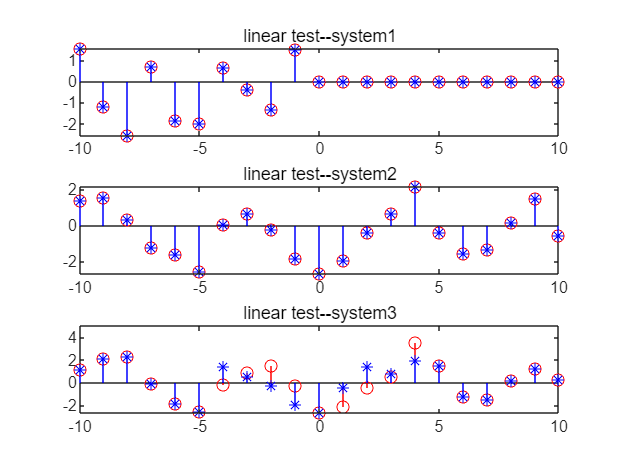

%2.7
%线性测试
n=-10:10;
x1=sin(n);
x2=(abs(n)<=4);
figure
subplot(3,1,1)
stem(n,bbox1(x1)+bbox1(x2),'r');
hold on
stem(n,bbox1(x1+x2),'b*');
title('linear test--system1');
subplot(3,1,2)
stem(n,bbox2(x1)+bbox2(x2),'r');
hold on
stem(n,bbox2(x1+x2),'b*');
title('linear test--system2');
subplot(3,1,3)
stem(n,bbox3(x1)+bbox3(x2),'r');
hold on
stem(n,bbox3(x1+x2),'b*');
title('linear test--system3');

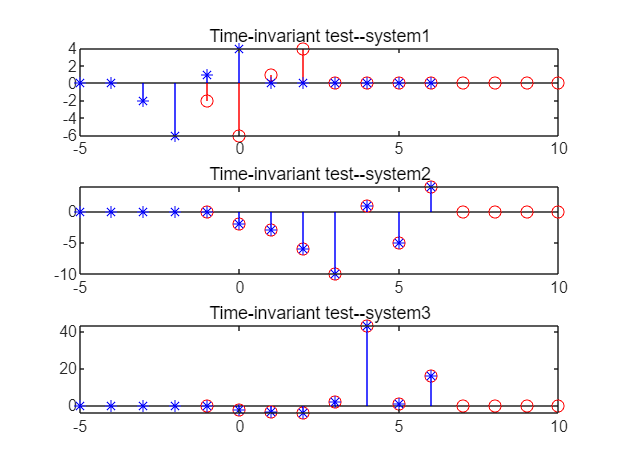

%时变测试
n=-5:6;
x1=[0 0 1 2 4 7 3 4 0 0 0 0];
x2=[0 0 0 0 0 0 1 2 4 7 3 4];
figure
subplot(3,1,1)
stem(n+4,bbox1(x1),'r');
hold on
stem(n,bbox1(x2),'b*');
xlim([-5,10])
title('Time-invariant test--system1');
subplot(3,1,2)
stem(n+4,bbox2(x1),'r');
hold on
stem(n,bbox2(x2),'b*');
xlim([-5,10])
title('Time-invariant test--system2');
subplot(3,1,3)
stem(n+4,bbox3(x1),'r');
hold on
stem(n,bbox3(x2),'b*');
xlim([-5,10])
title('Time-invariant test--system3');

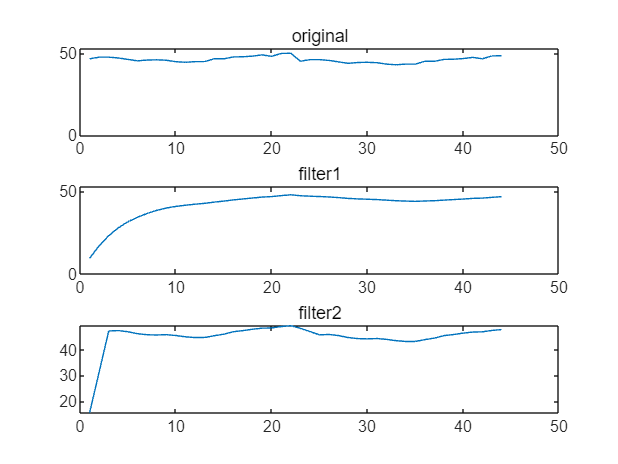

%2.8
load stockrates.mat
subplot(311)
n=1:length(rate);
plot(n,rate)
ylim([0 53])
title("original")
subplot(312)
dude = filter1(rate);
plot(n,dude)
title("filter1")
ylim([0 53])
subplot(313)
dude = filter2(rate);
ylim([0 53])
plot(n,dude)
title("filter2")